## Load Bbp data

bbp_dir = strcat(pwd, '/data');
cd(bbp_dir);
bbp_files = dir(fullfile(bbp_dir, 'bbp_*.csv'));

% Initialize an empty table
bbp_tbl = table();

% Loop through each file and append its contents
for i = 1:length(bbp_files)
    % Read the current CSV file
    tempTable = readtable(bbp_files(i).name);
    
    % Append to the combined table
    bbp_tbl = [bbp_tbl; tempTable]; % Concatenation
end

bbp_tbl = sortrows(bbp_tbl, 'date', 'ascend');
% Display the first 5 rows of the combined table
disp(bbp_tbl(1:min(5, height(bbp_tbl)), :));

            date            bbp_532nm      bbp_700nm 
    ____________________    __________    ___________

    01-Dec-2022 01:04:55    0.00075799     0.00011652
    01-Dec-2022 01:04:57    0.00090201     9.5774e-05
    01-Dec-2022 01:04:58    0.00061397     7.5026e-05
    01-Dec-2022 01:04:59      0.000854     0.00028251
    01-Dec-2022 01:05:00    0.00070998    -7.9674e-06



## Plot Bbp data

range_bbp = [0 0.03]

range_bbp =          0    0.0300


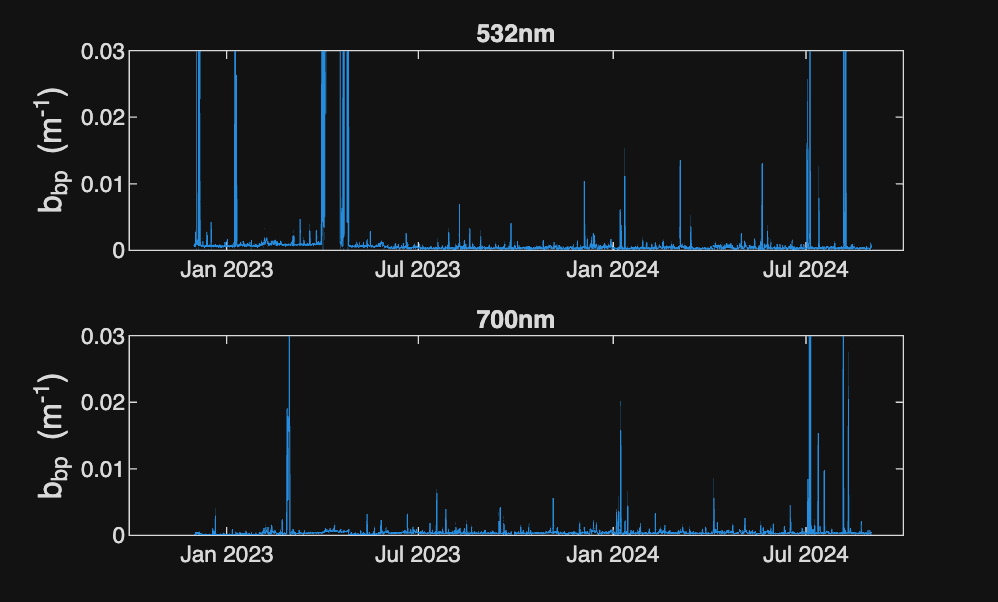


figure(1)
subplot(2,1,1)
    plot(bbp_tbl{:,1},bbp_tbl{:,2})
    title('532nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 
subplot(2,1,2)
    plot(bbp_tbl{:,1},bbp_tbl{:,3})
    title('700nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 

## Filter Bbp data

% Calculate the mean and standard deviation for bbp_532nm and bbp_700nm
mean532 = mean(bbp_tbl.bbp_532nm);
std532 = std(bbp_tbl.bbp_532nm);
mean700 = mean(bbp_tbl.bbp_700nm);
std700 = std(bbp_tbl.bbp_700nm);

% Define the thresholds for filtering
lowerThreshold532 = mean532 - 3 * std532;
upperThreshold532 = mean532 + 3 * std532;
lowerThreshold700 = mean700 - 3 * std700;
upperThreshold700 = mean700 + 3 * std700;

% Filter out data points outside 3 standard deviations
bbp_tbl = bbp_tbl(bbp_tbl.bbp_532nm >= lowerThreshold532 & bbp_tbl.bbp_532nm <= upperThreshold532 & ...
                  bbp_tbl.bbp_700nm >= lowerThreshold700 & bbp_tbl.bbp_700nm <= upperThreshold700, :);

## Smooth data

% Smooth input data
day_window = 14

day_window = 14

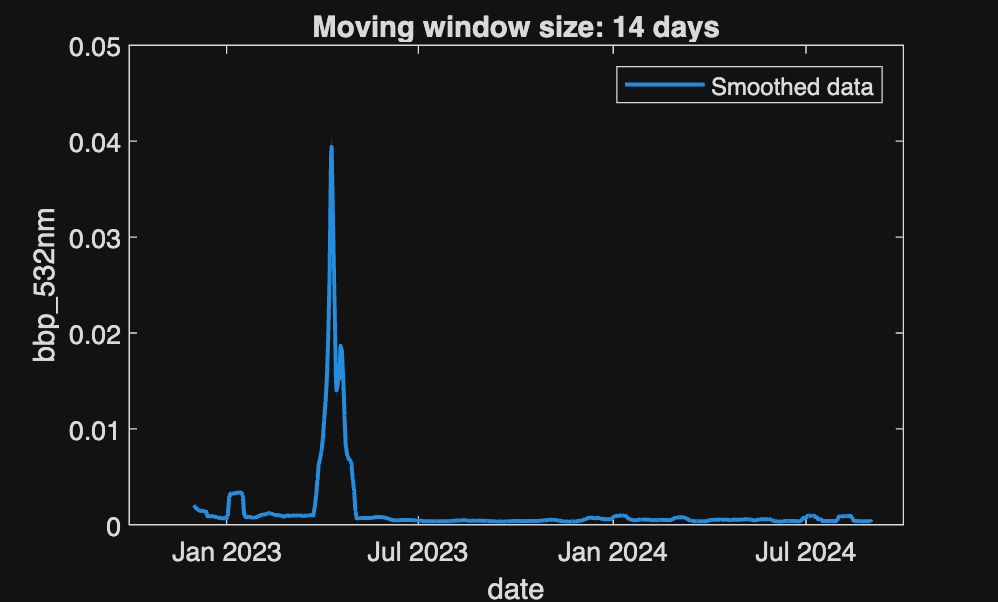

[smoothed532,winSize] = smoothdata(bbp_tbl(:,"bbp_532nm"),"movmean",days(day_window), ...
    SamplePoints=bbp_tbl.date);

% Display results
figure
plot(bbp_tbl.date,smoothed532.bbp_532nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize));
legend
ylabel("bbp_532nm",Interpreter="none")
xlabel("date")

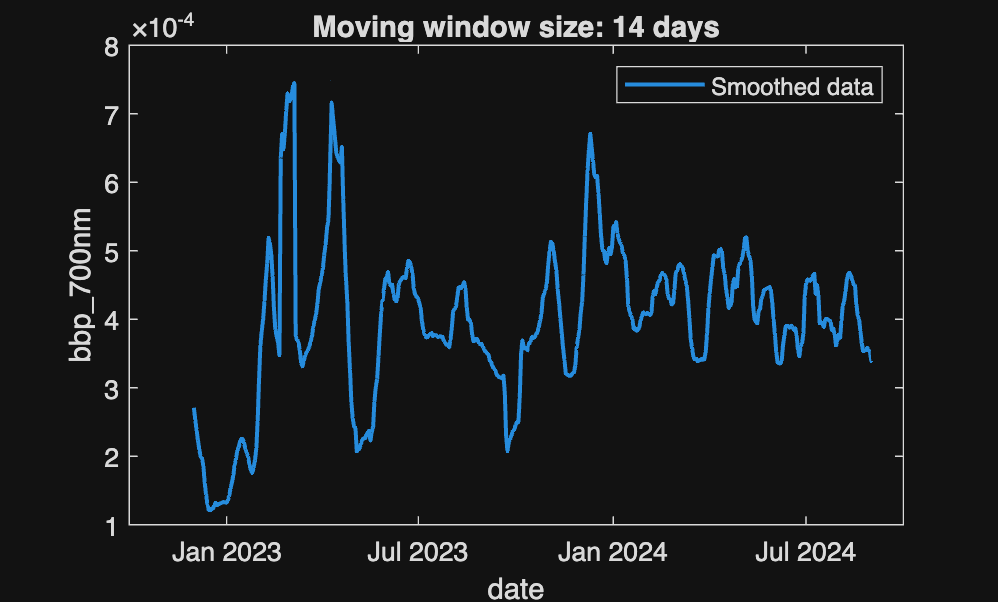


% Smooth input data
[smoothed700,winSize2] = smoothdata(bbp_tbl(:,"bbp_700nm"),"movmean",days(day_window), ...
    SamplePoints=bbp_tbl.date);

% Display results
figure
plot(bbp_tbl.date,smoothed700.bbp_700nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize2));
legend
ylabel("bbp_700nm",Interpreter="none")
xlabel("date")

clear winSize2

## Load and filter sediment trap data

trap_flux_tbl = readtable('trap_flux.csv');


% Exclude rows in trap_flux_tbl with Date values < 12/01/0022
trap_flux_tbl(trap_flux_tbl.Mid_Date < datetime(2022, 12, 1), :) = [];

% Display the first 10 rows of the trap flux table
disp(trap_flux_tbl(1:min(10, height(trap_flux_tbl)), :));

    Cup    Duration       Date        Mid_Date     JulianDay    Mid_Julian    tot_mass_flux    org_c_flux    caco3_flux    opal_flux    terr_flux    nitro_flux
    ___    ________    __________    __________    _________    __________    _____________    __________    __________    _________    _________    __________

     1        14       2022-12-01    2022-12-08      5449          5456          77.143            2.53        14.763        4.092       51.963         0.35   
     2        14       2022-12-15    2022-12-22      5463          5470          17.714           1.002        

## Plot sediment trap data

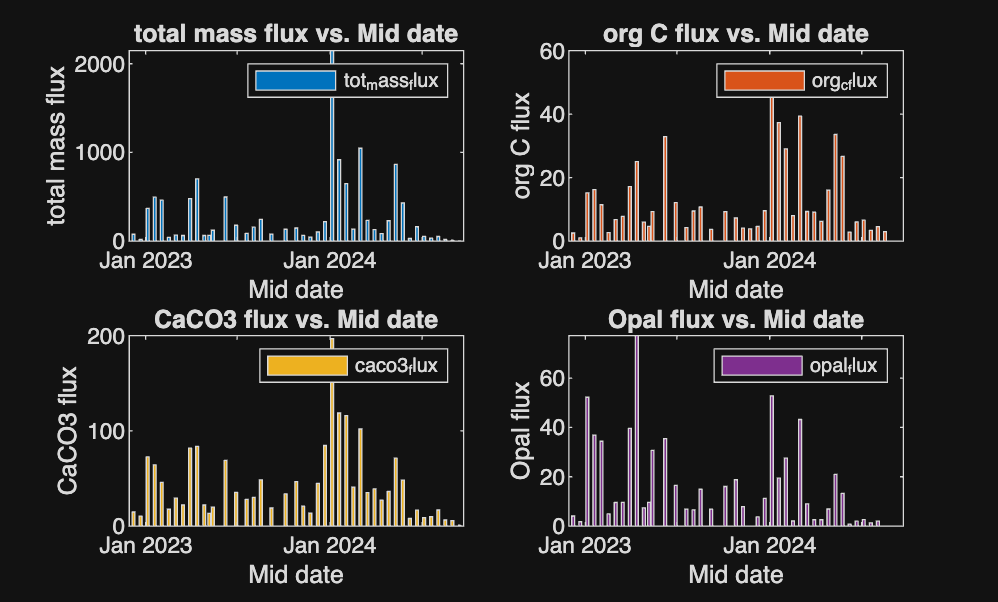

% Create a 2x2 subplot layout for the figures
figure

% Total Mass Flux
subplot(2,2,1)
h = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.tot_mass_flux, "DisplayName", "tot_mass_flux", 'FaceColor', [0 0.4470 0.7410]); % Blue
xlabel("Mid date")
ylabel("total mass flux")
title("total mass flux vs. Mid date")
legend

% Organic Carbon Flux
subplot(2,2,2)
h2 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.org_c_flux, "DisplayName", "org_c_flux", 'FaceColor', [0.8500 0.3250 0.0980]); % Red
xlabel("Mid date")
ylabel("org C flux")
title("org C flux vs. Mid date")
legend

% CaCO3 Flux
subplot(2,2,3)
h3 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.caco3_flux, "DisplayName", "caco3_flux", 'FaceColor', [0.9290 0.6940 0.1250]); % Yellow
xlabel("Mid date")
ylabel("CaCO3 flux")
title("CaCO3 flux vs. Mid date")
legend

% Opal Flux
subplot(2,2,4)
h4 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.opal_flux, "DisplayName", "opal_flux", 'FaceColor', [0.4940 0.1840 0.5560]); % Purple
xlabel("Mid date")
ylabel("Opal flux")
title("Opal flux vs. Mid date")
legend

## Overlay Bbp curves onto flux plots

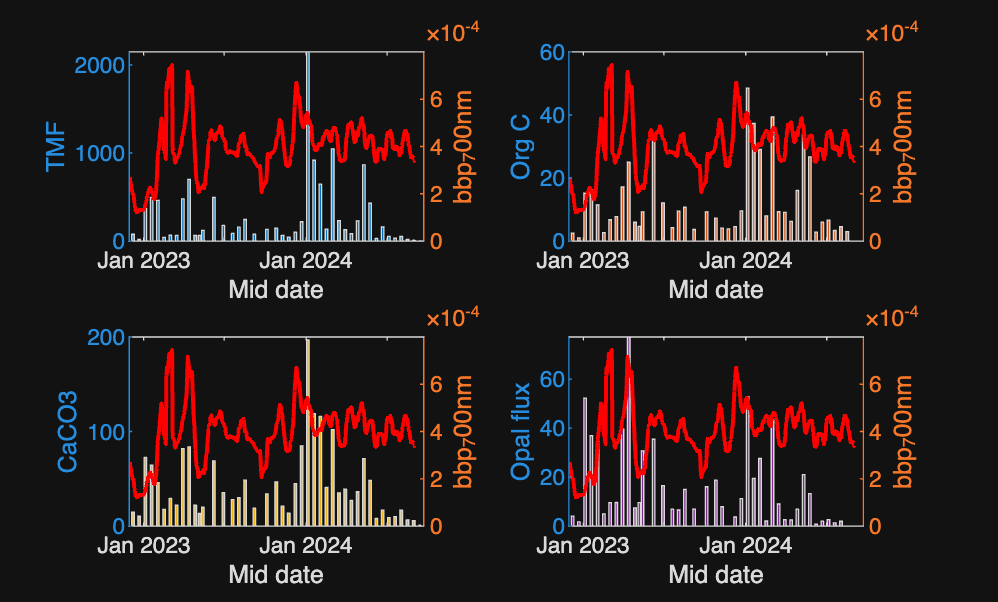

figure

% Create a 2x2 subplot layout for the figures
% Total Mass Flux
subplot(2,2,1)
yyaxis left
h5 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.tot_mass_flux, 'DisplayName', 'TMF', 'FaceColor', [0 0.4470 0.7410]); % Blue
ylabel('TMF')

yyaxis right
plot(bbp_tbl.date, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
ylabel('bbp_700nm')
xlabel('Mid date')
% legend('show')

% Organic Carbon Flux
subplot(2,2,2)
yyaxis left
h7 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.org_c_flux, 'DisplayName', 'Org C', 'FaceColor', [0.8500 0.3250 0.0980]); % Red
ylabel('Org C')

yyaxis right
plot(bbp_tbl.date, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
ylabel('bbp_700nm')
xlabel('Mid date')
% legend('show')

% CaCO3 Flux
subplot(2,2,3)
yyaxis left
h8 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.caco3_flux, 'DisplayName', 'CaCO3', 'FaceColor', [0.9290 0.6940 0.1250]); % Yellow
ylabel('CaCO3')

yyaxis right
plot(bbp_tbl.date, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
ylabel('bbp_700nm')
xlabel('Mid date')
% legend('show')

% Opal Flux
subplot(2,2,4)
yyaxis left
h6 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.opal_flux, 'DisplayName', 'Opal', 'FaceColor', [0.4940 0.1840 0.5560]); % Purple
ylabel('Opal flux')

yyaxis right
plot(bbp_tbl.date, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
ylabel('bbp_700nm')
xlabel('Mid date')

% legend('show')

## Calculate mean Bbp value for each cup cycle

% Initialize an empty table for results
avg_bbp_700_tbl = table();

% Loop through each row in trap_flux_tbl
for j = 1:height(trap_flux_tbl)
    % Define the date range
    startDate = trap_flux_tbl.Date(j);
    duration = trap_flux_tbl.Duration(j);
    endDate = startDate + duration;
    
    % Filter bbp_tbl for the date range
    filteredData = bbp_tbl(bbp_tbl.date >= startDate & bbp_tbl.date < endDate, :);
    
    % Calculate the average bbp_700 value
    if ~isempty(filteredData)
        avg_bbp_700 = mean(filteredData.bbp_700nm);
        std_bbp_700 = std(filteredData.bbp_700nm);
    else
        avg_bbp_700 = NaN; % Assign NaN if no data is available
        std_bbp_700 = NaN
    end

    tmf = trap_flux_tbl.tot_mass_flux(j);
    ogc_c = trap_flux_tbl.org_c_flux(j);
    caco3 = trap_flux_tbl.caco3_flux(j);
    opal = trap_flux_tbl.opal_flux(j);
    
    % Append the results to the table
    avg_bbp_700_tbl = [avg_bbp_700_tbl; table(startDate, endDate, avg_bbp_700, std_bbp_700, tmf, ogc_c, caco3, opal)];
end

std_bbp_700 = NaN


% Display the resulting table
disp(avg_bbp_700_tbl);

    startDate      endDate      avg_bbp_700    std_bbp_700     tmf      ogc_c     caco3      opal 
    __________    __________    ___________    ___________    ______    ______    ______    ______

    2022-12-01    2022-12-15    0.00019517     0.00024267     77.143      2.53    14.763     4.092
    2022-12-15    2022-12-29     0.0001319     0.00018801     17.714     1.002    10.404     1.745
    2022-12-29    2023-01-12    0.00015618     0.00023505     369.14    15.198     72.68    52.225
    2023-01-12    2023-01-26    0.00020879     0.00033478     495.43    16.196    64.349     36.89
    2023-01-26    2023-02-09    0.00036573     0.00038627     461.71    11.443    45.947    34.381
    2023-02-09    2023-02-23    0.

## Create least-square regression

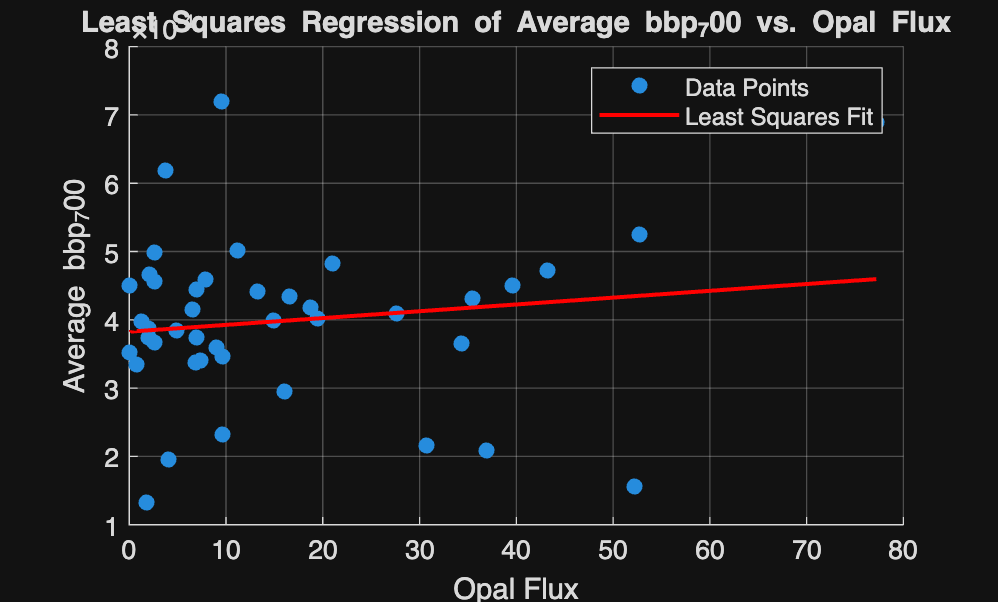

% Filter out NaN values from avg_bbp_700_tbl
avg_bbp_700_tbl = rmmissing(avg_bbp_700_tbl);

% Perform least squares regression
X = avg_bbp_700_tbl.opal(~isnan(avg_bbp_700_tbl.opal)); % Independent variable
Y = avg_bbp_700_tbl.avg_bbp_700(~isnan(avg_bbp_700_tbl.opal)); % Dependent variable

% Fit a linear model
p = polyfit(X, Y, 1); % p(1) is the slope, p(2) is the intercept

% Generate fitted values
Y_fit = polyval(p, X);

% Create a figure for the plot
figure
scatter(X, Y, 'filled', 'DisplayName', 'Data Points'); % Scatter plot of the data
hold on
plot(X, Y_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Least Squares Fit'); % Regression line
hold off

% Add labels and title
xlabel('Opal Flux');
ylabel('Average bbp_700');
title('Least Squares Regression of Average bbp_700 vs. Opal Flux');
legend('show');
grid on;